# Automatic phase correction method

clear all 
close all 
clc

% data set selection 
baseFolder='C:\Users\chiar\Documents\tesi IBEC doc\materials'

baseFolder = 'C:\Users\chiar\Documents\tesi IBEC doc\materials'

[file,path]=uigetfile(join([baseFolder,'\*.fid*']),'Load');
filename=sprintf('%s%s',path,file);
h=fopen(filename,'r');
fid_delay=fread(h,inf,'float'); 
fclose(h);

% loading .par file
file_par=replace(file, '_1.fid', '.par');
filename_par=sprintf('%s%s',path,file_par);
data_par=fopen(filename_par,'r');
data=textscan(data_par,'%s %f', 'Delimiter','\t');
fclose(data_par);

% transformation of data in .par format into .txt 
txtFile = replace(file_par,'.par','.txt'); 
parameters = fopen(txtFile, 'w');
for j = 1:length(data{1})
    fprintf(parameters, '%s %f\n', data{1}{j});
end
fclose(parameters);

% parameter selection 
desiredParameter = 'ReceiverPoints';
ReceiverPoints= matching_results(data, desiredParameter);

% if you are working with the carbon, put the space after the word
desiredParameter = 'SF ' ;
BaseFrequency = matching_results(data, desiredParameter); 
SF = str2double(BaseFrequency{2,1}); % X-Channel Base Frequency 

% if you are working with the carbon, put the space after the word
desiredParameter = 'O1 ';
OffsetFrequency = matching_results(data, desiredParameter); 
O1 = str2double(OffsetFrequency{2,1}); % X-Channel Frequency Offset [Hz]
points_rec=2*str2double(ReceiverPoints{2,1})*str2double(ReceiverPoints{3,1}); % Receiver Points (real and imaginary points)
points_act=length(fid_delay); % Actual  Point
delay = points_act-points_rec-1; 

fid=fid_delay(delay:end); % signal FID without delay 
n = length(fid); % number of rows 
M = repmat((1:n)',1,1); 
real_part=M(1:2:end,:); % odd matrix
real_fid = fid(real_part); 
img_part=M(2:2:end,:); % even matrix
img_fid = fid(img_part); 

new_fid = complex(real_fid, img_fid);

freq = linspace(-5208/2, 5208/2, length(new_fid)); % frequency 
t = linspace(1, 1/(freq(2)-freq(1)), length(new_fid)); % time
fid_spectrum = fft(new_fid); % fft 

ppm = ((freq-O1)/(SF));

y = flip((real(fftshift(fid_spectrum))));
[maxValue, maxIndex] = max(y);
corresponding_ppm = ppm(maxIndex(1));
shift = corresponding_ppm- 171;

% test using only the width of the higher peak 
[pksRlb,~, W12] = findpeaks(abs(real(fid_spectrum)), 'MinPeakHeight', max(abs(real(fid_spectrum))-1)); 
Rlb3 = pi*(freq(end)-freq(end-ceil(W12))); % rate constant
w = exp(-Rlb3*t); % weighting function 
fid_enhan= new_fid.*w'; 

DataBeforePhase= fft(fid_enhan); % stat signal 
DataBeforePhase = fftshift(DataBeforePhase');  % try to use the fft shifted 

DataSize = length( DataBeforePhase );
[maxVal ind] = max(abs(real(DataBeforePhase)));
pivot = ind; 
a_num = linspace(-pivot/DataSize, (-pivot+DataSize)/DataSize, DataSize);

% index = linspace(1,DataSize, DataSize);
% a_num = index-pivot;
% index = 1:DataSize;
% a_num = index-pivot; 
% a_num =ones(DataSize,1); 
% a_num(ind)=0; 
% a_num  =  -( ( 1:DataSize ) )  /  ( DataSize ); % vector from -1/DataSize to -1 (=-DataSIze/DataSize)


## another way to create a_num vector

% Calcola la distanza tra i sample
% distances = abs(DataSize- pivot);
% a_num = zeros(1,DataSize);
% a_num(distances < pivot) = -distances(distances < pivot);
% a_num(distances > pivot) = distances(distances > pivot);


## first step: coarse tuning

% DataBeforePhase=correctedSpectrum2;
%  search peak
PeakInfo  =  GetPeaks_Liquid( DataBeforePhase, 6, 0.0008 );

% get a group of the optimized phase from different initialization
Phase = zeros( 8,2 );
BaseContinuty = zeros( 8,1 );
options  =  optimset( 'TolFun', 1e-1, 'TolX', 0.01, 'MaxIter', 5000 );
for k = 1:2
    for i = 1:4
        InitiaPh0Test  =  0 +  k * 90;
        InitiaPh1Test = -180  +  ( i-1 ) * 90;
        [Phase( i + ( k-1 ) * 4, : ), BaseContinuty( i + ( k-1 ) * 4 )]  =  fminsearch( @( Phase )MinPeakContinuity_Liquid(  Phase, DataBeforePhase, PeakInfo ), [InitiaPh0Test, InitiaPh1Test], options ); % DA CAMBIARE ALGORITMO DI OTTIMIZZAZIONE 
    end
end

% select the optimized phase from the group
[MinBaseContinuty, Index]  =  sort( BaseContinuty );
FinalPhase  =  Phase( Index( 1 ),: );
PhaseDataAfterCon  =  zeros( 1, length( DataBeforePhase ) );
iCount  =  2;
while( abs( FinalPhase( 2 ) ) > 300  && iCount <=  length( BaseContinuty ) );
%    msgbox( '最优一阶相位值超过300' );
   FinalPhase  =  Phase( Index( iCount ),: );
   iCount  =  iCount  +  1;
end
if ( iCount > length( BaseContinuty ) ) 
    msgbox( 'cannot find the best phase value！' );
    FinalPhase  =  Phase( Index( 1 ), : );
end
% correct the spectra by coarse tuning result
phi = (pi/180)*(FinalPhase( 1 )  + FinalPhase( 2 ) * a_num);  % (pi/180) 
R = real(DataBeforePhase).*cos(phi) - imag(DataBeforePhase).*sin(phi); 
I = real(DataBeforePhase).*sin(phi) + real(DataBeforePhase).*sin(phi); 
PhaseDataAfterCon = complex(R, I);

% correction = exp( j * pi / 180 * ( FinalPhase( 1 )  + FinalPhase( 2 ) * a_num ));
% PhaseDataAfterCon  =  DataBeforePhase.* correction;

[ MaxPeakValue, MaxPeakIndex ]  =  max( abs( real( PhaseDataAfterCon ) ) );
if( real( PhaseDataAfterCon( MaxPeakIndex ) ) < 0 )
    PhaseDataAfterCon  =  -PhaseDataAfterCon;
end 


## second step: fine tuning

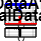

% calculate the cwt factor according to the full width of half height of spectra
PeakInfo  =  GetPeaks( real( PhaseDataAfterCon ), 6, 0.001 );
Weight  =  ones( length( DataBeforePhase ), 1 );
for i  =  1 : length( PeakInfo )
    Weight( PeakInfo( i ).Start : PeakInfo( i ).End )  =  0;
end
Baseline  =  AutoBaseCorr_Liquid( real( PhaseDataAfterCon ), Weight, DataSize ); % automatic baseline correction
[PeakValue, PeakIndex] =  PickPeakForPhase( real( PhaseDataAfterCon )-Baseline', 8 );
MaxHalfWidth  =  GetMaxHalfWidthForPhase( real( PhaseDataAfterCon )-Baseline', PeakIndex );

cwtfactor =  MaxHalfWidth  /  DataSize;
    cwtfactor  =  0.0008;
if( MaxHalfWidth < 5  )
    cwtfactor  =  0.0008;
end
if( MaxHalfWidth > DataSize / 16 )
    cwtfactor  =  0.0008;
end
if( length( MaxHalfWidth )  ==  0 )
    cwtfactor  =  0.0008;
end
PeakInfo  =  GetPeaks_Liquid( real( PhaseDataAfterCon ), 6, cwtfactor ); 

% initialize the weight of peak and baseline by prak information, 0 is
% peak; 1 is baseline
Weight = ones( length( DataBeforePhase ),1 );
for i = 1 : length( PeakInfo )
    Weight( PeakInfo( i ).Start:PeakInfo( i ).End ) = 0;
end

% get the baseline
Baseline = AutoBaseCorr_Liquid( real( PhaseDataAfterCon )', Weight, DataSize );
Baseline= Baseline';
% identify the positive peak，negative peak and distorted peak
IdentifyResult = IdentifyPeak_Liquid(  PeakInfo, real( PhaseDataAfterCon ) - Baseline');

% get the optimized phase 
options = optimset( 'TolFun', 1, 'TolX', 0.1, 'MaxIter', 100 );
% [NegativePhase,NegativeArea,exitflag,output] = fminsearch( @( Phase )NewNegativePenlty_Liquid( Phase, PhaseDataAfterCon, PeakInfo, IdentifyResult, Weight, a_num' ),[0,0],options );
[NegativePhase,NegativeArea,exitflag,output] = fminSearchTest_Liquid( @( Phase )NewNegativePenlty_Liquid( Phase, PhaseDataAfterCon, PeakInfo, IdentifyResult, Weight, DataSize ),[0,0],options );

% correct the spectra by coarse tuning result
phi = (pi/180)*(NegativePhase( 1 )  + NegativePhase( 2 ) * a_num');  % (pi/180) 
R = real(PhaseDataAfterCon).*cos(phi)' - imag(PhaseDataAfterCon).*sin(phi)'; 
I = real(PhaseDataAfterCon).*sin(phi)' + real(PhaseDataAfterCon).*sin(phi)'; 
DataAfterNegative = complex(R, I);

% DataAfterNegative = PhaseDataAfterCon' .*  exp( j * pi / 180 * ( NegativePhase( 1 ) + ( NegativePhase( 2 ) ) * a_num ) );
% pahse0 = FinalPhase( 1 )  +  NegativePhase( 1 );
% phase1 = FinalPhase( 2 )  +  NegativePhase( 2 );
% phase = [pahse0 phase1];

% FinalData = PhaseDataAfterCon' .*  exp( j * pi / 180 * ( phase(1) + (phase(2)) * a_num ) ); 

figure;
subplot(3, 1, 1);
plot(freq, real((DataBeforePhase)), 'b', 'LineWidth', 1.5);
title('DataBeforePhase');
axis tight;
grid on;

subplot(3, 1, 2);
plot(freq, real((PhaseDataAfterCon)), 'r', 'LineWidth', 1.5);
title('PhaseDataAfterCon');
axis tight;
grid on;

subplot(3, 1, 3);
plot(freq, real((DataAfterNegative)), 'k', 'LineWidth', 1.5);
title('FinalDataFft');
axis tight;
grid on;

disp( 'over' )

over


% figure; 
% plot(freq, real((PhaseDataAfterCon)), 'r', 'LineWidth', 1.5);
% hold on 
% plot(freq, real((DataAfterNegative)), 'k', 'LineWidth', 1);
% hold off

% PROVA ESTRAZIONE DIVERSI FID SIGNAL ASSOCIATI A DIVERSE FREQUENZE 
% [pksDataAfterNegative] = findpeaks(abs(real(fid_spectrum)), 'MinPeakHeight', max(abs(real(fid_spectrum))-1)); 

% abs_DataAfterNegative = abs(real((DataAfterNegative))); 
% [peaks locs] = findpeaks(abs_DataAfterNegative, 'MinPeakHeight', 6*10^4);
% freq_peaks = freq(locs);
% bandwidth = 8; 
% extracted_component = ifft(ifftshift((abs(freq - freq_peaks(1)) < bandwidth) .* DataAfterNegative'));
% 
% pval = [NegativePhase, pivot];